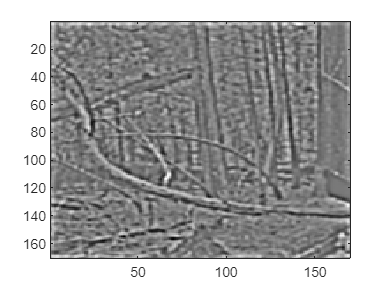

% coursework quiz questions
% question 1
DoG_mask = fspecial('gaussian', 9, 1.0) - fspecial('gaussian', 9, 1.5);

I_q1 = imread('woods.png');
I_q1 = im2double(I_q1);

Image_DoG = conv2(I_q1, DoG_mask, 'same');
figure(); clc; imagesc(Image_DoG); colormap('gray'); 


Image_DoG(29, 7)

ans = -0.0059

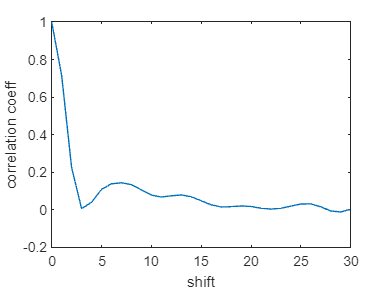


offsets = [0:30];
coeff_values = zeros(1, 30);
for offset = offsets
   coeff_values(offset+1) = corr2(Image_DoG(1:end-offset,:),Image_DoG(1+offset:end,:));
end

figure(), clf, plot(offsets,coeff_values); xlabel('shift'); ylabel('correlation coeff')

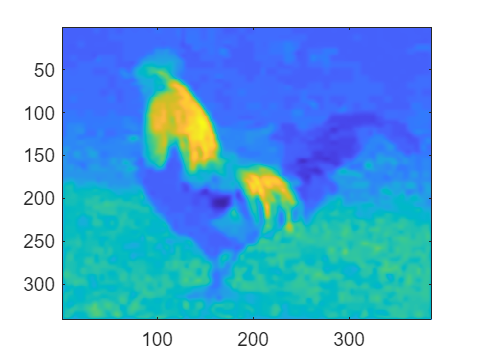

% question 2
I_q2 = imread('rooster.jpg');
I_q2 = im2double(I_q2);

gaussian_mask = fspecial('gaussian', 11, 1.85);
Y=mean(I_q2(:,:,1:2),3);

I_q2_YB = conv2(Y, gaussian_mask,'same') - conv2(I_q2(:,:,3), gaussian_mask,'same');
figure(); clc; imagesc(I_q2_YB); 


I_q2_YB(272, 5)

ans = 0.2321

I_q2_YB(174, 255)

ans = -0.0752

% question 3
laplacian_mask = [-1/8 -1/8 -1/8; -1/8 1 -1/8; -1/8 -1/8 -1/8];

gaussian_mask_small = fspecial("gaussian", 9, 1.5); 
gaussian_mask_large = fspecial("gaussian", 30, 5);

LoG_small_conv = conv2(gaussian_mask_small, laplacian_mask, "same");
LoG_large_conv = conv2(gaussian_mask_large, laplacian_mask, "same");

subplot(2,2,1); mesh(LoG_small_conv); colormap('default'); title('Small LoG');
subplot(2,2,2); mesh(LoG_large_conv); colormap('default'); title('Large LoG');

I = imread('woods.png');
I = im2double(I);

I_LoG_small = conv2(I, LoG_small_conv, "same");
I_LoG_large = conv2(I, LoG_large_conv, "same");

subplot(2,2,3); imagesc(I_LoG_small); colormap('gray'); title('Image Small LoG')
subplot(2,2,4); imagesc(I_LoG_large); colormap('gray'); title('Image Large LoG');

I_LoG_small(114,49)
I_LoG_small(155,42)

I_LoG_large(114,49)
I_LoG_large(155,42)

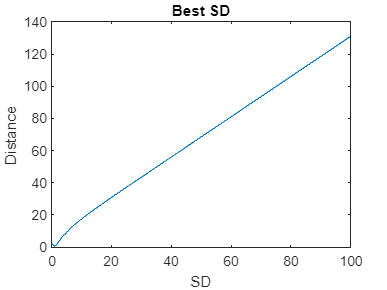

% question 4

sd_used = zeros(1, 1000);
euclidean_distance = zeros(1, 1000);

for i = 0:0.10:100
    sd_g0 = 5;
    sd_g1 = i + 3;
    sd_g2 = i + 6;

    LoG_gaussian_mask = fspecial('gaussian', round(6*sd_g2), sd_g0);
    DoG_mask = fspecial('gaussian', round(6*sd_g2), sd_g1) - fspecial('gaussian', round(6*sd_g2), sd_g2);
    LoG_mask = conv2(LoG_gaussian_mask, LoG_laplacian_mask, "same");
    
    LoG = LoG_mask./max(max(LoG_mask));
    DoG = DoG_mask./max(max(DoG_mask));

    sd_used(uint16(i*10 + 1)) = i;
    euclidean_distance(uint16(i*10 + 1)) = sqrt(sum(sum((DoG-LoG).^2)));
end

figure(); clc; plot(sd_used, euclidean_distance); title('Best SD'); xlabel('SD'); ylabel('Distance');


[val_best_sd, idx_best_sd] = min(euclidean_distance);
val_best_sd

val_best_sd = 0.4578

best_sd = sd_used(idx_best_sd)

best_sd = 0.9000

% question 4 - experimental 

LoG_gaussian_mask = fspecial('gaussian', 36, 5);
LoG_laplacian_mask = [-1/8 -1/8 -1/8; -1/8 1 -1/8; -1/8 -1/8 -1/8];

DoG_mask = fspecial('gaussian', 36, 3) - fspecial('gaussian', 36, 6);
LoG_mask = conv2(LoG_gaussian_mask, LoG_laplacian_mask, "same");

LoG = LoG_mask./max(max(LoG_mask));
DoG = DoG_mask./max(max(DoG_mask));
euclidean_distance = sqrt(sum(sum((DoG-LoG).^2)))

euclidean_distance = 2.4529

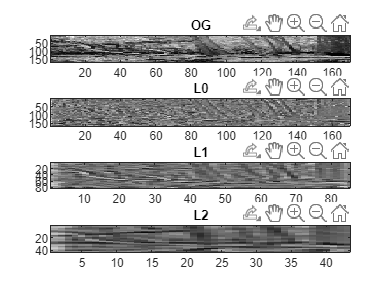

% question 5
I = imread('woods.png');
I = im2double(I);

gaussian_mask = fspecial('gaussian', 9, 1.5);

I_gaussian_pyramid_1 = conv2(I, gaussian_mask, "same");
I_laplacian_pyramid_1 = imsubtract(I, I_gaussian_pyramid_1);

I_gaussian_resized_2 = imresize(I_gaussian_pyramid_1, 0.5, "nearest");

I_gaussian_pyramid_2 = conv2(I_gaussian_resized_2, gaussian_mask, "same");
I_laplacian_pyramid_2 = imsubtract(I_gaussian_resized_2, I_gaussian_pyramid_2);

I_gaussian_resized_3 = imresize(I_gaussian_pyramid_2, 0.5, "nearest");

I_gaussian_pyramid_3 = conv2(I_gaussian_resized_3, gaussian_mask, "same");
I_laplacian_pyramid_3 = imsubtract(I_gaussian_resized_3, I_gaussian_pyramid_3);

figure(); clc;
subplot(4,1,1); imagesc(I); colormap('gray'); title('OG');
subplot(4,1,2); imagesc(I_laplacian_pyramid_1); colormap('gray'); title('L0');
subplot(4,1,3); imagesc(I_laplacian_pyramid_2); colormap('gray'); title('L1');
subplot(4,1,4); imagesc(I_laplacian_pyramid_3); colormap('gray'); title('L2');


I_laplacian_pyramid_3(6, 8)

ans = -0.0331

I_laplacian_pyramid_3(2, 2)

ans = 0.1759

% question 6

I = imread('elephant.png');

Error using imread>get_full_filename
File "elephant.png" does not exist.

Error in imread (line 372)
        fullname = get_full_filename(filename);

I = im2double(I);

orientations = [0,15,30,45,60,75,90,105,120,135,150,165];
images_generated = {0,0,0,0,0,0,0,0,0,0,0,0};
for i = 1:12
    filter = gabor2(3,0.1,orientations(i),0.75,90);
    images_generated{i} = conv2(I, filter, "valid");
end

final_image = repmat(-1,[484 484]);
for k = 1:484 
    for j = 1:484
        for l = 1:12
            if images_generated{l}(k,j) > final_image(k, j)
                final_image(k,j) = images_generated{l}(k,j);
            end
        end
    end
end

figure(); clc; imagesc(final_image); colormap('gray'); 

            
final_image(281,256)
final_image(23,3)
